setenv('ROS_DOMAIN_ID','0');
ros2 topic list

/parameter_events
/rosout
/yolo_webcam_image


ros2 node list

/image_subscriber_node
/yolo_webcam_node


node = ros2node('image_subscriber_node');
sub = ros2subscriber(node, '/yolo_webcam_image', 'sensor_msgs/Image');

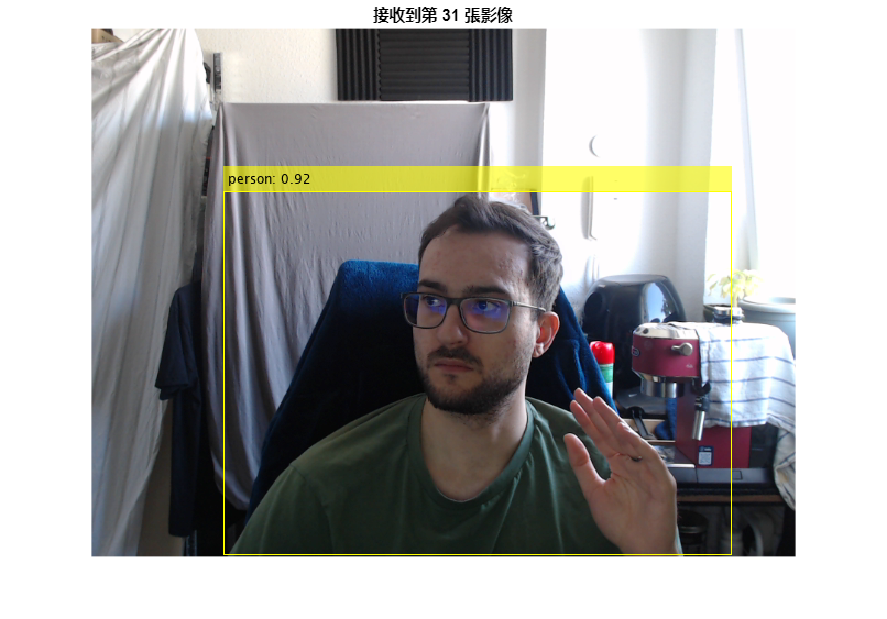


for i = 1:50

    msg = receive(sub, 10);

    img = rosReadImage(msg);  

    imshow(img);
    title(['Frame ', num2str(i), ' Webcam']);
    drawnow;
end